# Part 1: Extracting Features using Computer Vision

In this session you will learn the fundamentals of computer vision (Part 1) and machine learning ([Part 2](matlab:open('./Part2_ClassifyingAnomalies.mlx'))) to develop a classifier capable of discriminating normal tissue from cancerous tissue. To do so, we will be working with data captured during a surgical procedure using an endoscopic near-infrared fluorescence imaging system. This system simultaneously captures and displays videos in both the visible white-light and near-infrared spectrums.

In Part 1, using the visible white-light video, you will see how to use computer vision to automatically detect and track features points. These tracked points are used to compute the geometric transformation between the current point locations and the initial point locations. This transformation is then used to perform [image registration](https://www.mathworks.com/help/images/image-registration.html), which warps the current frame to keep features aligned with the initial frame. With each near-infrared video frame aligned to the same reference frame, the mean fluorescence intensity time histories of a grid of regions can be quickly computed across each warped intensity frame.

### Setup Video Reader and Display Initial Frame

Setup a [`VideoReader`](https://www.mathworks.com/help/matlab/ref/videoreader.html) and set initial and final video times for analysis. Read and display the initial video frame using [`readFrame`](https://www.mathworks.com/help/matlab/ref/videoreader.readframe.html) and [`imshow`](https://www.mathworks.com/help/matlab/ref/imshow.html), respectively. 

Note, in this case the path to the video file was already managed when the [MATLAB Project](https://www.mathworks.com/help/matlab/projects.html) (`AnomalyClassification.prj`) was opened. You can create and use projects in MATLAB to find files required to run your code, manage and share files and settings, and interact with source control.

video  = VideoReader( "AMST_0001.mp4" );
tInit  = 2;   % seconds
tFinal = 122; % seconds
video.CurrentTime = tInit;
frame = readFrame( video );

figure
imshow( frame )
title( "Initial Color and Intensity Frames" )

Use [`imcrop`](https://www.mathworks.com/help/images/ref/imcrop.html) to separate the visible light color frame (`cframe`) on top from the near-infrared intensity frame (`iframe`) on bottom. Use [`im2gray`](https://www.mathworks.com/help/matlab/ref/im2gray.html) to ensure the intensity frame is grayscale.

w = video.Width;
h = video.Height/2;
cframe = imcrop( frame, [0 0 w h] );
iframe = imcrop( frame, [0 h+1 w h] );
iframe = im2gray( iframe );

### Detect Control Points and Initialize Point Tracker

We will use the [Kanade-Lucas-Tomasi (KLT) algorithm](https://uk.mathworks.com/help/vision/ug/face-detection-and-tracking-using-the-klt-algorithm.html) to track control points over time. The initial control points are detected using the standard "Good Features to Track" proposed by Shi and Tomasi ([`detectMinEigenFeatures`](https://www.mathworks.com/help/vision/ref/detectmineigenfeatures.html)). To improve performance, we'll limit the number of tracked points such that they are uniformly distributed across the video frame ([`selectUniform`](https://www.mathworks.com/help/vision/ref/kazepoints.selectuniform.html)).

maxPts = 30;
pts = detectMinEigenFeatures( im2gray( cframe ), ...
    ROI=[0.05*[w h] 0.9*[w h]] ); % set ROI away from frame edges
pts = selectUniform( pts, maxPts, [h w] );
points1 = pts.Location;

Setup and intialize a [vision point tracker](https://www.mathworks.com/help/vision/ref/vision.pointtracker-system-object.html) [system object](https://www.mathworks.com/help/matlab/matlab_prog/what-are-system-objects.html). System objects are designed specifically for implementing and simulating dynamic systems with inputs that change over time.

tracker = vision.PointTracker( MaxBidirectionalError=1 );
initialize( tracker, points1, cframe );

Display the detected feature points using [`insertMarker`](https://www.mathworks.com/help/vision/ref/insertmarker.html). (We'll add a second marker `"o"` for better visibility.)

cmarked = insertMarker( cframe, points1 );
cmarked = insertMarker( cmarked, points1, "o" );

figure
imshow( cmarked )
title( "Detected Feature Points" )

### Setup a Grid of Regions

In Part 2, we will be classifying the full field-of-view of the video frame. While in general pixel-by-pixel classification is possible (e.g. [semantic segmentation](https://www.mathworks.com/solutions/image-video-processing/semantic-segmentation.html)), for this problem such resolution can significantly increase computing and labeling requirements unnecessarily, and is more susceptible to signal noise (e.g. due to imperfect video stabilization). As such, we will instead setup a grid of regions (`nRows` by `nCols`) to balance these concerns against the resolution required for clinical purposes.

nRows = 18;
nCols = 24;
nRegs = nRows*nCols;      % number of grid regions
hReg  = ceil( h/nRows );  % height of each grid region
wReg  = ceil( w/nCols );  %  width of each grid region

The `region` variable used by [`insertShape`](https://www.mathworks.com/help/vision/ref/insertshape.html) is an `nRegs` by 4 array containing the position and size of each grid region in spatial coordinates, specified in the form `[xmin ymin width height]`. The `[xmin ymin]` coordinates, which represent the upper left corner of each region, can be created using the [`meshgrid`](https://www.mathworks.com/help/matlab/ref/meshgrid.html) function.

[X,Y] = meshgrid( 0.5+(0:(nCols-1))*wReg, 0.5+(0:(nRows-1))*hReg );
region = [X(:) Y(:) min(wReg,w+0.5-X(:)) min(hReg,h+0.5-Y(:))];

Display the resulting grid regions on the intensity frame.

imarked = insertShape( iframe, Rectangle=region, Color="white" );

figure
imshow( imarked )
title("Grid of Regions")

### Compute Grid Region Initial Intensities

Setup an averaging kernel (`Kavg`) and use this [convolution](https://www.mathworks.com/discovery/convolution.html) matrix to compute the corresponding mean intensity value for each grid region.

Kavg = ones( [hReg wReg] ) / prod( [hReg wReg] );
Igrid = conv2( iframe, Kavg, "same" );

The [`conv2`](https://www.mathworks.com/help/matlab/ref/conv2.html) `"same"` flag ensures the output (`Igrid`) returns only the central part of the convolution, which is the same size as `iframe`. The mean value for each grid region then corresponds to the convolution value at the center of each grid region.

rows = hReg*(1:nRows) - round(hReg/2);
cols = wReg*(1:nCols) - round(wReg/2);
Igrid = Igrid(rows,cols);

As a side note, we could also achieve similar results using [`imresize`](https://www.mathworks.com/help/matlab/ref/imresize.html) with a "box"-shaped kernel.

Visualize the computed initial grid intensities as an image with scaled colors ([`imagesc`](https://www.mathworks.com/help/matlab/ref/imagesc.html)). For visualization purposes the maximum initial intensity value is displayed here as white. However, note in the color bar that this actually corresponds to less than 10% of 255.

figure
imagesc( Igrid )
colormap( gray )
colorbar
axis image

xticks( 1:nCols )
yticks( 1:nRows )
xlabel( "Grid Column" )
ylabel( "Grid Row" )
title( "Initial Grid Region Intensities" )

### Accelerate Code with GPU Computing

The [built-in multithreading](https://www.mathworks.com/discovery/matlab-multicore.html) feature in MATLAB automatically parallelizes computations for many linear algebra and numerical functions, including `conv2`. Since MATLAB does this implicitly, you do not need to enable it manually.

You can often further speed up your code by [running MATLAB functions on a GPU](https://www.mathworks.com/help/parallel-computing/run-matlab-functions-on-a-gpu.html). If you do not have a GPU available locally, you can use one or more high-performance NVIDIA [GPUs in the cloud](https://www.mathworks.com/help/parallel-computing/run-matlab-using-cloud-gpus.html). You can use Cloud Center to create, manage, and access machines on AWS with MATLAB already installed. You can then access these machines from a web browser or a remote desktop application. To learn more, see [Start MATLAB on Amazon Web Services (AWS) Using Cloud Center](https://www.mathworks.com/help/cloudcenter/ug/start-matlab-on-amazon-web-services-aws-using-cloud-center.html).

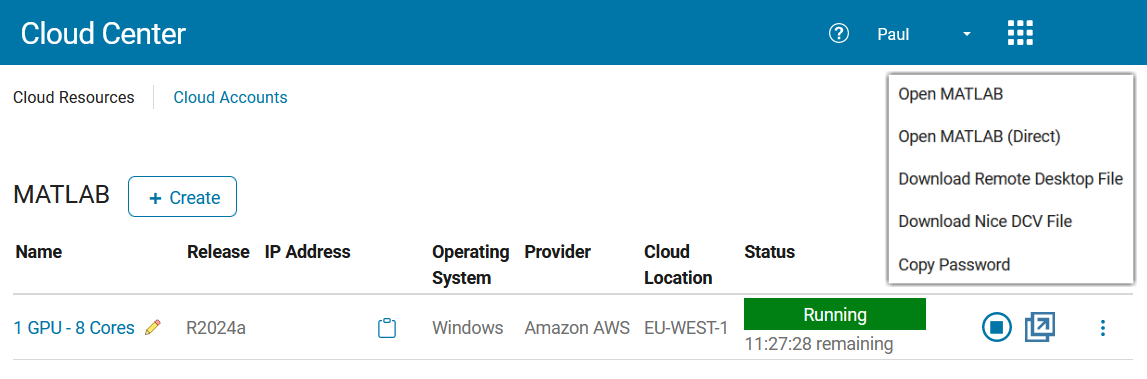

If a supported GPU is available for computation ([`canUseGPU`](https://www.mathworks.com/help/matlab/ref/canusegpu.html)), we will use [`gpuArray`](https://www.mathworks.com/help/parallel-computing/gpuarray.html) to copy an array to the GPU. A large number of functions support `gpuArray` objects, allowing you to run your code on GPUs with minimal changes to the code. To find a full list of `gpuArray`-enabled functions, see [GPU-supported functions](https://www.mathworks.com/help/referencelist.html?type=function&capability=gpuarrays). If you want to retrieve the array from the GPU, for example when using a function that does not support `gpuArray` objects, use the [`gather`](https://www.mathworks.com/help/parallel-computing/gpuarray.gather.html) function.

Kavg = ones( [hReg wReg] ) / prod( [hReg wReg] );

maxNumCompThreads(1); % use 1 computational thread
tCpu = timeit( @() conv2( iframe, Kavg, "same" ) );
disp( "CPU Time (1 Thread): " + 1e3*tCpu + " ms" )

maxNumCompThreads("automatic"); % use max computational threads
numThreads = maxNumCompThreads;
tCpu = timeit( @() conv2( iframe, Kavg, "same" ) );
disp( "CPU Time (" + numThreads + " Threads): " + 1e3*tCpu + " ms" )

useGpu = canUseGPU;
if useGpu
    Kavg = gpuArray( Kavg );
    img  = gpuArray( iframe );
    tGpu = gputimeit( @() conv2( img, Kavg, "same" ) );

    gpu = gpuDevice;
    disp( "GPU Time (" + gpu.Name + "): " + 1e3*tGpu + " ms" )
    disp( "GPU Speedup: " + round(tCpu/tGpu,1) + "x" )
else
    disp( "Unable to find a supported GPU device." )
end

### Process Video to Compute Intensity Time Histories

Setup a [`vision.VideoPlayer`](https://www.mathworks.com/help/vision/ref/vision.videoplayer-system-object.html) to display the processed video frames, and pre-allocate memory to store results.

player = vision.VideoPlayer( Position=[965 45 435 605] );
player( vertcat( cmarked, imarked ) ) % open video player

nFrames = ceil( (tFinal-tInit)*video.FrameRate );
time = NaN( 1, nFrames );
Iregion = NaN( [[nRows nCols] nFrames], "single" );
if useGpu
    Iregion = gpuArray( Iregion );
end

Store initial values and intialize all grid regions as valid (`gid`). Setup a registered output view (`OV`) for image registration.

time(1) = tInit;
Iregion(:,:,1) = Igrid;
gid = true( nRegs, 1 );
OV = imref2d( [h w] );

To extract the intensity time histories, we will loop over each video frame as follows:

- Read and separate next video frame ([`readFrame`](https://www.mathworks.com/help/matlab/ref/videoreader.readframe.html) and [`imcrop`](https://www.mathworks.com/help/images/ref/imcrop.html))

- Track points from frame to frame ([`vision.PointTracker`](http://vision.pointtrackerhttps//www.mathworks.com/help/vision/ref/vision.pointtracker-system-object.html))

- Compute corresponding geometric transformation ([`fitgeotform2d`](https://www.mathworks.com/help/images/ref/fitgeotform2d.html))

- Warp current frame to align with initial frame ([`imwarp`](https://www.mathworks.com/help/images/ref/imwarp.html))

- Compute grid region intensity using 2-D convolution ([`conv2`](https://www.mathworks.com/help/matlab/ref/conv2.html))

k = 1; tic
while hasFrame( video ) && isOpen( player ) && (video.CurrentTime <= tFinal)
    k = k + 1;
    time(k) = video.CurrentTime;

    % 1) Read and separate next video frame
    frame  = readFrame( video );
    cframe = imcrop( frame, [0 0 w h] );   % color frame (top half)
    iframe = imcrop( frame, [0 1+h w h] ); % intensity frame (bottom half)
    iframe = im2gray( iframe );

    % 2) Track points from frame to frame
    [points,pval] = tracker( cframe );

    % 3) Compute corresponding geometric transformation
    if (nnz(pval) < 3) % requires at least 3 valid points
        k = k - 1;
        break
    end
    tform = fitgeotform2d( points(pval,:), points1(pval,:), "affine" );

    if useGpu
        % Store arrays on GPU
        cframe = gpuArray( cframe );
        iframe = gpuArray( iframe );
    end

    % 4) Warp current frame to align with initial frame
    creg = imwarp( cframe, tform, OutputView=OV );
    ireg = imwarp( iframe, tform, OutputView=OV );

    % 5) Compute grid region intensity using 2-D convolution
    Igrid = single( ireg );      % NaN not allowed for uint8
    Igrid(all(creg==0,3)) = NaN; % ignore black padding due to warping
    Igrid = conv2( Igrid, Kavg, "same" );
    Iregion(:,:,k) = Igrid(rows,cols); % extract grid regions

    if useGpu
        % Transfer data back to CPU (for VideoPlayer)
        creg = gather( creg );
        ireg = gather( ireg );
    end

    % Flag invalid regions due to warping
    rval = ~isnan( Iregion(:,:,k) );
    gid = (gid & rval(:));

    % Mark color and intensity frames with tracked points
    % Note, transformed points will appear relatively fixed
    xy = transformPointsForward( tform, points(pval,:) );
    cmarked = insertMarker( creg, xy );
    imarked = insertShape( ireg, "rectangle", region(gid,:), Color="white" );
    player( vertcat( cmarked, imarked ) ) % display in video player
end
toc

% Clean up
release( player )
release( tracker )

If processing stops early, remove unused pre-allocated values by extracting values from 1 to `k`. For easier data analysis and plotting, [`reshape`](https://www.mathworks.com/help/matlab/ref/reshape.html) `Iregion` from a multidimensional array (`nRows` by `nCols` by `k`) to a matrix (`nRegs` by `k`).

time = time(1:k);
Iregion = reshape( Iregion(:,:,1:k), nRegs, k );
gid = find( gid ); % find valid grid indices

if useGpu
    % Transfer data back to CPU
    Iregion = gather( Iregion ); % for smoothdata
    iframe  = gather( iframe );  % for insertShape
end

### Examine and Explore Results

In Part 2 we will use ***supervised*** learning to train a classifier to differentiate cancerous regions from negative regions, which will require labeling our data. Without labeled data we can still use ***unsupervised*** *k*-means [clustering analysis](https://www.mathworks.com/discovery/cluster-analysis.html) to partition the fluorescence intensity time histories of each region into *k* distinct groups.  Although cluster analysis will not necessarily represent or differentiate classes of interest (e.g. cancer versus negative), it can be helpful for finding hidden patterns or groupings in a data set.

First we will reduce noise in the fluorescence intensity time histories (for each valid grid region) using the [`smoothdata`](https://www.mathworks.com/help/matlab/ref/smoothdata.html) function (along time, dimension 2). Then, we will use the [`kmeans`](https://www.mathworks.com/help/stats/kmeans.html) function to cluster these smoothed time signals into `nGroups`. We can compute the mean signal for each group (displayed in black) using [`grpstats`](https://www.mathworks.com/help/stats/grpstats.html). Finally, we will use [`insertShape`](https://www.mathworks.com/help/vision/ref/insertshape.html) to color code each valid region on the intensity frame to correspond to its group color in the time histories plot.

nGroups = 3;
Ismooth = smoothdata( Iregion(gid,:), 2, SmoothingFactor=0.1 );
grp = kmeans( Ismooth, nGroups );
Igroup = grpstats( Ismooth, grp, "mean" );
cmap = lines( nGroups ); % colormap

figure
colororder( cmap(grp,:) )
plot( time, Ismooth )
hold on; grid on
plot( time, Igroup, Color="white", LineWidth=3 )
plot( time, Igroup, Color="black", LineWidth=1 )
xlabel("Video Time (sec)")
ylabel("Fluorescence Intensity [0 255]")
title("Clustered Intensity Time Histories")

figure
marked = insertShape( iframe, "filled-rectangle", region(gid,:), ...
    Color=255*cmap(grp,:), Opacity=0.2 );
marked = insertMarker( marked, points(pval,:), "+", Color="white" );
imshow( marked )
title("Corresponding Grid Regions")

*Copyright 2024 The MathWorks, Inc.*